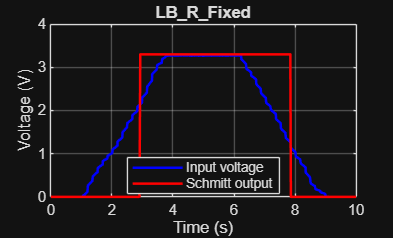

S = load('C:\Users\Admin\Desktop\RMX\Lab\poten\data.mat', 'LB_R_Fixed');

sigIn  = getElement(S.LB_R_Fixed, 1);
sigOut = getElement(S.LB_R_Fixed, 2);

vin  = sigIn.Values;
vout = sigOut.Values;

figure;
plot(vin.Time, squeeze(vin.Data), 'b', 'LineWidth', 1.5);
hold on;
plot(vout.Time, squeeze(vout.Data), 'r', 'LineWidth', 1.5);
grid on;

xlabel('Time (s)');
ylabel('Voltage (V)');
title('LB_R_Fixed', 'Interpreter', 'none');
legend('Input voltage', 'Schmitt output', 'Location', 'best');
xlim([0 10]);